clear all;
clc;

% --------------------------------------------------%
% Forward Kinematics Calculator
% Gets transform from End-effector to base (T0_ee)
%---------------------------------------------------%

syms theta1 theta2 theta3 real
syms a1 a2 a3 real
syms d1 d2 d3 real
syms alpha1 alpha2 real

% DH parameters
% Each element is for a particular transform from a joint frame {i-1} to
% {i}
alpha = [0 pi/2 -pi/2 0]

alpha =          0    1.5708   -1.5708         0


a = [0 0 0 1]

a =      0     0     0     1


d = [d1 d2 0 0]

$$d = \left(\begin{array}{cccc} d_{1} & d_{2} & 0 & 0 \end{array}\right)$$

theta = [-pi/2 -pi/2 theta3 0]

$$theta = \left(\begin{array}{cccc} -\frac{\pi }{2} & -\frac{\pi }{2} & \theta_{3} & 0 \end{array}\right)$$


% Parameter ranges
d1_range = linspace(6,7, 50);
d2_range = linspace(4,5, 50);
theta3_range = arr2Rad(linspace(0,360, 180));

[d1_grid, d2_grid, theta3_grid] = ndgrid(d1_range, d2_range, theta3_range);

% Create arrays of every possible value tuple
d1_vals = reshape(d1_grid, 1, []);
d2_vals = reshape(d2_grid, 1, []);
theta3_vals = reshape(theta3_grid, 1, []);

% Create identity matrix for multiplication
T0_ee = eye(4)

T0_ee =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1



% Apply each transformation
for i = 1:length(alpha)
    T{i} = TF(a(i),alpha(i),d(i),theta(i));
    T0_ee = T0_ee*T{i};
end

% Yields output 
disp('Symbolic output')

Symbolic output


T0_ee

$$T0\_ee = \begin{array}{l} \left(\begin{array}{cccc} \sin\left(\theta_{3}\right)-\sigma_{2} & \cos\left(\theta_{3}\right)+\sigma_{1} & -\frac{4967757600021511}{81129638414606681695789005144064} & \sin\left(\theta_{3}\right)-\sigma_{2}-d_{2}\\ -\sigma_{1} & -\sigma_{2} & -1 & -\sigma_{1}\\ -\cos\left(\theta_{3}\right)-\sigma_{1} & \sin\left(\theta_{3}\right)-\sigma_{2} & \frac{24678615572571482867467662723121}{6582018229284824168619876730229402019930943462534319453394436096} & d_{1}+\frac{4967757600021511\,d_{2}}{81129638414606681695789005144064}-\cos\left(\theta_{3}\right)-\sigma_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{4967757600021511\,\sin\left(\theta_{3}\right)}{81129638414606681695789005144064}\\ \sigma_{2}=\frac{4967757600021511\,\cos\left(\theta_{3}\right)}{81129638414606681695789005144064} \end{array}$$


% Have Matlab simplify
disp('Simplified Symbolic output')

Simplified Symbolic output


Ts = vpa(simplify(T0_ee))

$$Ts = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & \cos\left(\theta_{3}\right)-\sigma_{2} & -0.00000000000000006123233995736766035868820147292 & \sin\left(\theta_{3}\right)-0.00000000000000006123233995736766035868820147292\,\cos\left(\theta_{3}\right)-1.0\,d_{2}\\ \sigma_{2} & -0.00000000000000006123233995736766035868820147292\,\cos\left(\theta_{3}\right) & -1.0 & \sigma_{2}\\ -1.0\,\cos\left(\theta_{3}\right)+\sigma_{2} & \sigma_{1} & 3.7493994566546441699929521964488e-33 & d_{1}+0.00000000000000006123233995736766035868820147292\,d_{2}-1.0\,\cos\left(\theta_{3}\right)+\sigma_{2}\\ 0 & 0 & 0 & 1.0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{3}\right)-0.00000000000000006123233995736766035868820147292\,\cos\left(\theta_{3}\right)\\ \sigma_{2}=-0.00000000000000006123233995736766035868820147292\,\sin\left(\theta_{3}\right) \end{array}$$


% Replace symbols with real values for a result
disp('Symbolic output with real values')

Symbolic output with real values


x = T0_ee(1,4)

$$x = \sin\left(\theta_{3}\right)-\frac{4967757600021511\,\cos\left(\theta_{3}\right)}{81129638414606681695789005144064}-d_{2}$$

y = T0_ee(2,4)

$$y = -\frac{4967757600021511\,\sin\left(\theta_{3}\right)}{81129638414606681695789005144064}$$

z = T0_ee(3,4)

$$z = d_{1}+\frac{4967757600021511\,d_{2}}{81129638414606681695789005144064}-\cos\left(\theta_{3}\right)-\frac{4967757600021511\,\sin\left(\theta_{3}\right)}{81129638414606681695789005144064}$$


% Sanity-check. We use a near-zero threshold as there are always precision
% errors in floating point operations
if ~any(arrayfun(@(i) isAlways(abs(i)<0.0001),[x y z]))
    error('At least one position needs to be 0 in the 2D case')
end

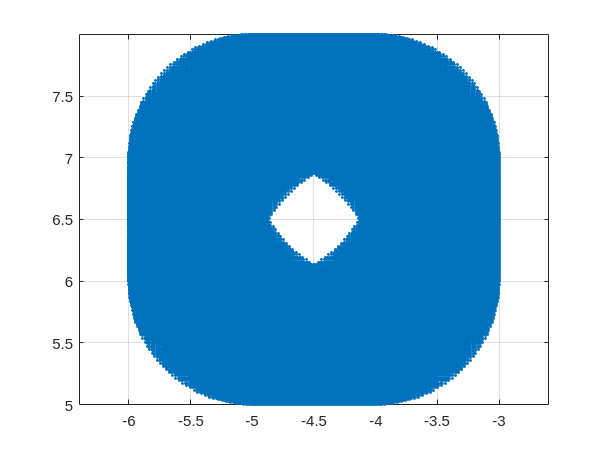


% Convert from symbolic to numerical functions for faster evaluation
x_func = matlabFunction(x);
y_func = matlabFunction(y);
z_func = matlabFunction(z);


% Calculate positions
x_out = x_func(d2_vals,theta3_vals);
% y_out = y_func(d2_vals,theta3_vals);
z_out = z_func(d1_vals, d2_vals, theta3_vals);
% 
% Plot
figure(1)
plot(x_out,z_out,'.')
axis equal
grid on

function out = arr2Rad(A)
    out = arrayfun(@(angle) deg2rad(angle), A);
end
function T = TF(a,alpha,d,theta)
% Generic link transform function that generates a homogeneous transform
% matrix from the DH parameters.
T = [cos(theta) -sin(theta) 0 a
     sin(theta)*cos(alpha) cos(theta)*cos(alpha) -sin(alpha) -sin(alpha)*d
     sin(theta)*sin(alpha) cos(theta)*sin(alpha)  cos(alpha)  cos(alpha)*d
     0 0 0 1];
end